Controllo se è rimasta aperta la porta seriale

if(exist('STM32_ser', 'var'))
    delete(STM32_ser);
end

baudrate = 1000000

baudrate = 1000000

porte_libere = serialportlist("available")

porte_libere = "COM9"

STM32_ser = serialport(porte_libere(end), baudrate , Timeout=2);

Connetto alla seriale

buff_size = 400;
measures = 2;

Numero_Misure = 100000

Numero_Misure = 10000

l =  buff_size*measures

l = 800

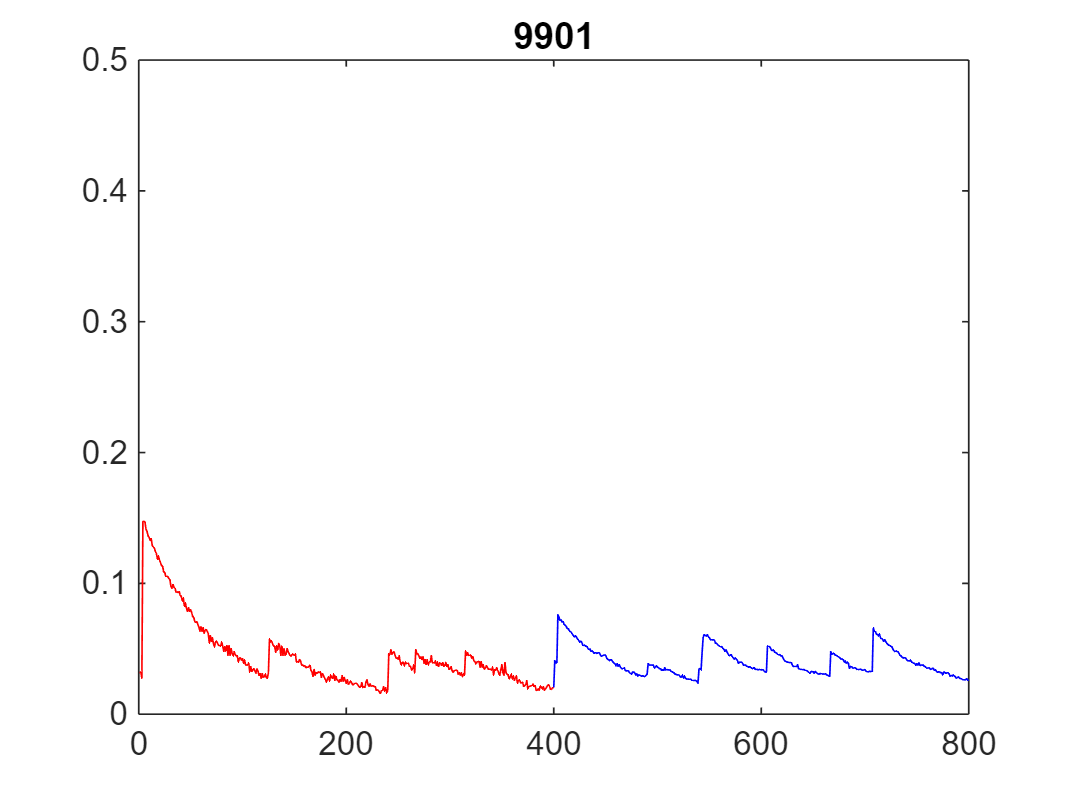

data_buffer = zeros(Numero_Misure, l);
index = 1;

tic
while (index < Numero_Misure+1)
% while 1

    STM32_ser.write('?','char');
    data = STM32_ser.read(l,'uint16') ./ 2^16 * 3.3;
    
    data_buffer(index, :) = data;
    if mod(index, 100)==1
        figure(1);
        plot(1:l/2, data(1:l/2), 'r', l/2:l, data(l/2:l), 'b' )
        ylim([0,.5]);
        title(index);
        drawnow
    end
    index = index +1;
end

toc

Elapsed time is 310.801844 seconds.


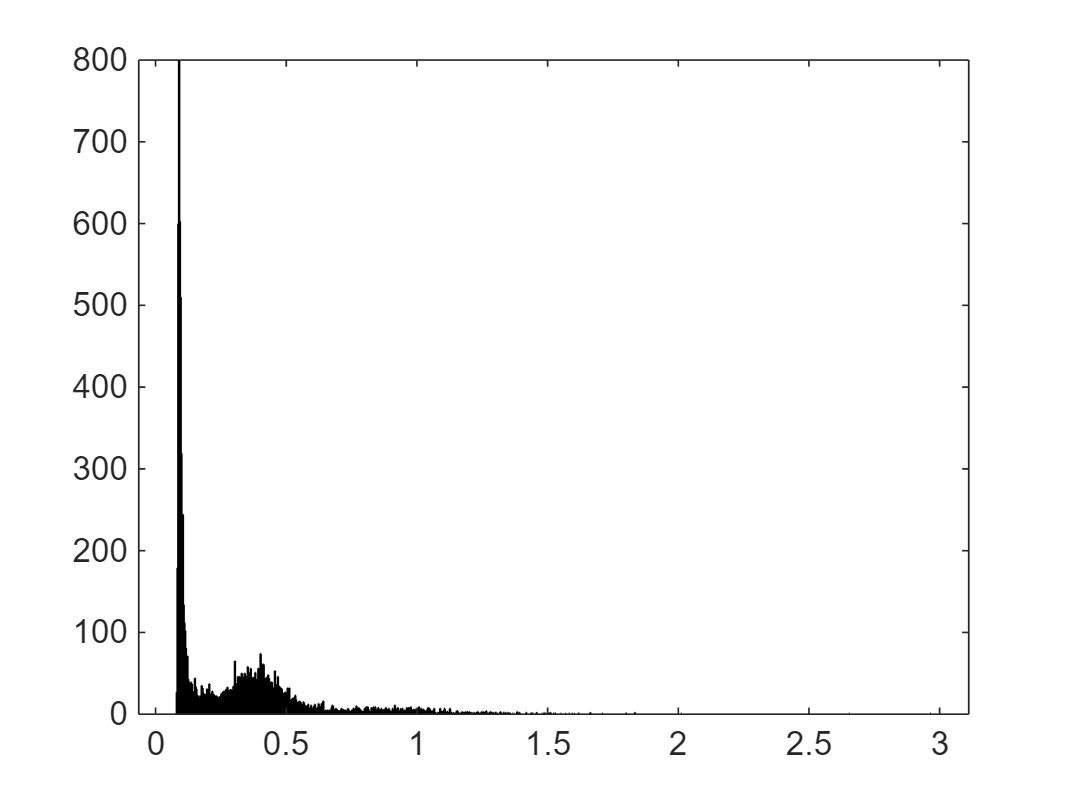

max_val = zeros(0,Numero_Misure);
for i=1:Numero_Misure
    max_val(i) = data_buffer(i,15);
end

max_val2 = zeros(0,Numero_Misure);
for i=1:Numero_Misure
    max_val2(i) = data_buffer(i,400+15);
end
histogram(max_val, 1000)

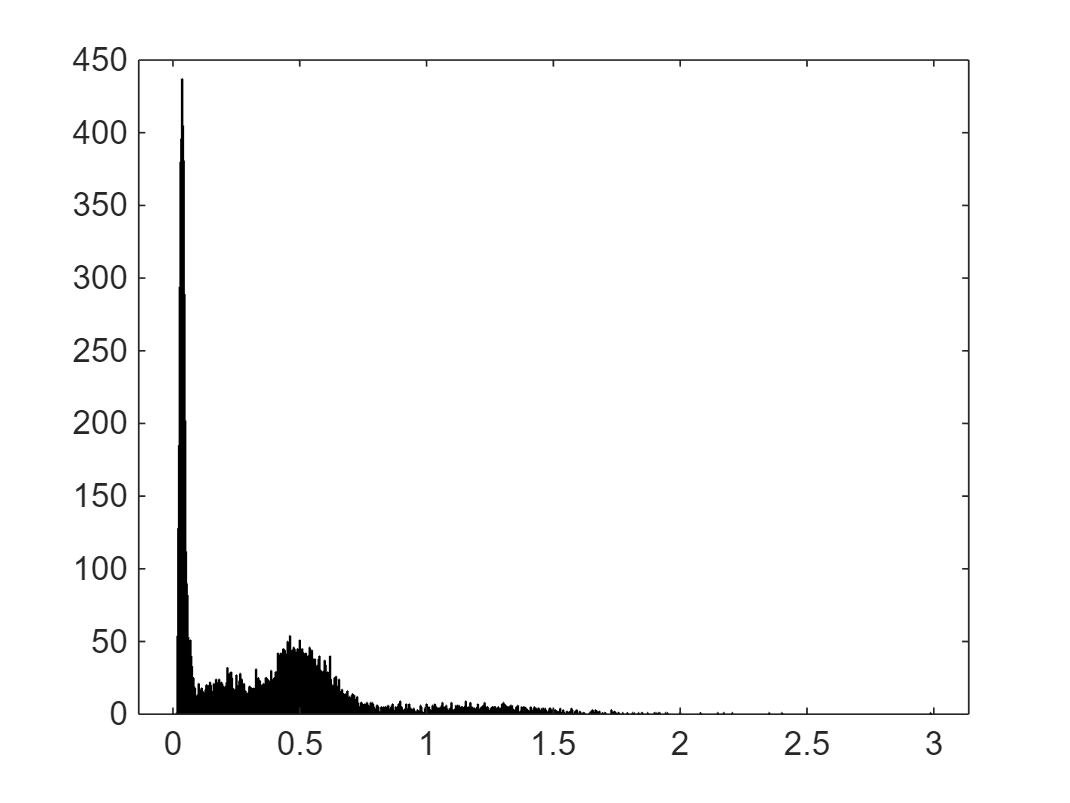

histogram(max_val2, 1000)